# Machine Learning: Programming Exercise 3

## Multi-class Classification and Neural Networks

In this exercise, you will implement one-vs-all logistic regression and neural networks to recognize hand-written digits.

### Files needed for this exercise

- `ex3.mlx` - MATLAB Live Script that steps you through the exercise

- `ex3data1.mat` - Training set of hand-written digits

- `ex3weights.mat` - Initial weights for the neural network exercise

- `submit.m `- Submission script that sends your solutions to our servers

- `displayData.m` - Function to help visualize the dataset

- `fmincg.m` - Function minimization routine (similar to `fminunc`)

- `sigmoid.m` - Sigmoid function

- `*lrCostFunction.m` - Logistic regression cost function

- `*oneVsAll.m` - Train a one-vs-all multi-class classifier

- `*predictOneVsAll.m` - Predict using a one-vs-all multi-class classifier

- `*predict.m `- Neural network prediction function

****indicates files you will need to complete***

#### Clear existing variables and confirm that your Current Folder is set correctly

Click into this section, then click the 'Run Section' button above. This will execute the `clear` command to clear existing variables and the `dir` command to list the files in your Current Folder. The output should contain all of the files listed above and the 'lib' folder. If it does not, right-click the 'ex3' folder and select 'Open' before proceding or see the instructions in `README.mlx` for more details.

clear
dir

.                  displayData.m      ex3_companion.mat  ex3data1.mat       fmincg.m           lrCostFunction.m   predict.m          sigmoid.m          
..                 ex3.mlx            ex3_companion.mlx  ex3weights.mat     lib                oneVsAll.m         predictOneVsAll.m  submit.m           



### Before you begin

The workflow for completing and submitting the programming exercises in MATLAB Online differs from the original course instructions. Before beginning this exercise, make sure you have read through the instructions in `README.mlx` which is included with the programming exercise files. `README` also contains solutions to the many common issues you may encounter while completing and submitting the exercises in MATLAB Online. Make sure you are following instructions in `README` and have checked for an existing solution before seeking help on the discussion forums.

## 1. Multi-class Classification

For this exercise, you will use logistic regression and neural networks to recognize handwritten digits (from 0 to 9). Automated handwritten digit recognition is widely used today - from recognizing zip codes (postal codes) on mail envelopes to recognizing amounts written on bank checks. This exercise will show you how the methods you've learned can be used for this classication task. In the first part of the exercise, you will extend your previous implemention of logistic regression and apply it to one-vs-all classification.

### 1.1 Dataset

You are given a data set in `ex3data1.mat` that contains 5000 training examples of handwritten digits*. The .mat format means that that the data has been saved in a native MATLAB matrix format, instead of a text (ASCII) format like a csv-file. These matrices can be read directly into your program by using the load command. After loading, matrices of the correct dimensions and values will appear in your program's memory. The matrix will already be named, so you do not need to assign names to them. 

**This is a subset of the MNIST *[*handwritten digit dataset*](http://yann.lecun.com/exdb/mnist/)

Run the code below to load the data.

% Load saved matrices from file
load('ex3data1.mat');
% The matrices X and y will now be in your MATLAB environment

    There are 5000 training examples in `ex3data1.mat`, where each training example is a 20 pixel by 20 pixel grayscale image of the digit. Each pixel is represented by a floating point number indicating the grayscale intensity at that location. The 20 by 20 grid of pixels is 'unrolled' into a 400-dimensional vector. Each of these training examples becomes a single row in our data matrix `X`. This gives us a 5000 by 400 matrix `X` where every row is a training example for a handwritten digit image.


$$X=\left\lbrack \begin{array}{c}
-{\left(x^{\left(1\right)} \right)}^T -\\
-{\left(x^{\left(2\right)} \right)}^T -\\
\vdots \\
-{\left(x^{\left(m\right)} \right)}^T -
\end{array}\right\rbrack$$


    The second part of the training set is a 5000-dimensional vector `y` that contains labels for the training set. To make things more compatible with MATLAB indexing, where there is no zero index, we have mapped the digit zero to the value ten. Therefore, a '0' digit is labeled as '10', while the digits '1' to '9' are labeled as '1' to '9' in their natural order.

## 1.2 Visualizing the data

You will begin by visualizing a subset of the training set. The code below randomly selects selects 100 rows from `X` and passes those rows to the `displayData` function. This function maps each row to a 20 pixel by 20 pixel grayscale image and displays the images together. We have provided the `displayData` function, and you are encouraged to examine the code to see how it works. After you run this step, you should see an image like Figure 1.

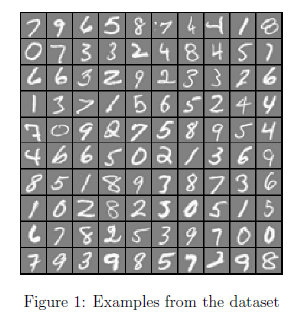                        

m = size(X, 1);
% Randomly select 100 data points to display
rand_indices = randperm(m);
sel = X(rand_indices(1:100), :);
displayData(sel);

### 1.3 Vectorizing logistic regression

You will be using multiple one-vs-all logistic regression models to build a multi-class classifier. Since there are 10 classes, you will need to train 10 separate logistic regression classifiers. To make this training efficient, it is important to ensure that your code is well vectorized. In this section, you will implement a vectorized version of logistic regression that does not employ any `for` loops. You can use your code in the last exercise as a starting point for this exercise.

#### 1.3.1 Vectorizing the cost function

We will begin by writing a vectorized version of the cost function. Recall that in (unregularized) logistic regression, the cost function is


$$J(\theta) =\frac{1}{m}\sum_{i=1}^m{\left[

-y^{(i)} \log(h_{\theta}(x^{(i)}))- (1-y^{(i)}) \log(1- h_{\theta}(x^{(i)}))\right],$$


To compute each element in the summation, we have to compute $h_{\theta}(x^{(i)})$ for every example $i$, where $h_{\theta}(x^{(i)}) = g(\theta^T x^{(i)})$ and $g(z) =\frac{1}{1+e^{-z}}$ is the sigmoid function. It turns out that we can compute this quickly for all our examples by using matrix multiplication. Let us define $X$ and $\theta$ as


$$X\theta \;=\left\lbrack \begin{array}{c}
-{\left(x^{\left(1\right)} \right)}^T \theta \;-\\
-{\left(x^{\left(2\right)} \right)}^T \theta \;-\\
\vdots \\
-{\left(x^{\left(m\right)} \right)}^T \theta \;-
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
-\;\theta^T \left(x^{\left(1\right)} \right)-\\
-{\;\theta }^T \left(x^{\left(2\right)} \right)\;-\\
\vdots \\
-{\;\theta }^T \left(x^{\left(m\right)} \right)-
\end{array}\right\rbrack \;$$


In the last equality, we used the fact that $a^T b= b^T a$ if $a$ and $b$ are vectors. This allows us to compute the products $\theta^T x^{(i)}$ for all our examples $i$ in one line of code.

    Your job is to write the unregularized cost function in the file `lrCostFunction.m `Your implementation should use the strategy we presented above to calculate $\theta^T x^{(i)}$. You should also use a vectorized approach for the rest of the cost function. A fully vectorized version of `lrCostFunction.m` should not contain any loops. (Hint: You might want to use the element-wise multiplication operation (`.*`) and the sum operation `sum` when writing this function)

#### 1.3.2 Vectorizing the gradient

Recall that the gradient of the (unregularized) logistic regression cost is a vector where the $j$th element is defined as 


$$\frac{\partial J(\theta)}{\partial \theta_j} = \frac{1}{m}\sum_{i=1}^m{\left( h_\theta(x^{(i)})-y^{(i)}\right)x_j^{(i)}
$$


To vectorize this operation over the dataset, we start by writing out all the partial derivatives explicitly for all $\theta_j$,

$\left[ \begin{array}{c} 
\frac{\partial J(\theta)}{\partial \theta_0} \\
\frac{\partial J(\theta)}{\partial \theta_1} \\
\frac{\partial J(\theta)}{\partial \theta_2} \\
\vdots \\
\frac{\partial J(\theta)}{\partial \theta_n}   
 \end{array} \right]
 = \frac{1}{m}
\left[ \begin{array}{c} 
\sum_{i=1}^m{\left( h_\theta(x^{(i)})-y^{(i)}\right)x_0^{(i)} \\
\sum_{i=1}^m{\left( h_\theta(x^{(i)})-y^{(i)}\right)x_1^{(i)} \\
\sum_{i=1}^m{\left( h_\theta(x^{(i)})-y^{(i)}\right)x_2^{(i)} \\
\vdots \\
\sum_{i=1}^m{\left( h_\theta(x^{(i)})-y^{(i)}\right)x_n^{(i)}
\end{array}\right] =\frac{1}{m} \sum_{i=1}^m{\left( h_\theta(x^{(i)})-y^{(i)}\right)x^{(i)} =
\frac{1}{m}X^T {\left( h_\theta(x)-y\right)}
$   (1)

where


$$h_{\theta \;} \left(x\right)-y=\left\lbrack \begin{array}{c}
h_{\theta \;} \left(x^{\left(1\right)} \right)-y^{\left(1\right)} \\
h_{\theta \;} \left(x^{\left(2\right)} \right)-y^{\left(2\right)} \\
\vdots \\
h_{\theta \;} \left(x^{\left(m\right)} \right)-y^{\left(m\right)} 
\end{array}\right\rbrack$$


    Note that $x^{(i)}$ is a vector, while $(h_\theta(x^{(i)})-y^{(i)})$ is a scalar (single number). To understand the last step of the derivation, let $\beta_i = (h_\theta(x^{(i)})-y^{(i)})$ and observe that:


$$\sum_i \beta_i x^{\left(i\right)} =\left\lbrack \begin{array}{cccc}
| & | & \; & |\\
x^{\left(1\right)}  & x^{\left(2\right)}  & \dots  & x^{\left(m\right)} \\
| & | & \; & |
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
\beta_1 \\
\beta_2 \\
\vdots \\
\beta_m 
\end{array}\right\rbrack =X^T \beta ,$$


    The expression above allows us to compute all the partial derivatives without any loops. If you are comfortable with linear algebra, we encourage you to work through the matrix multiplications above to convince yourself that the vectorized version does the same computations. You should now implement Equation (1) to compute the correct vectorized gradient. Once you are done, complete the function `lrCostFunction.m` by implementing the gradient.

**Debugging Tip: **Vectorizing code can sometimes be tricky. One common strategy for debugging is to print out the sizes of the matrices you are working with using the size function. For example, given a data matrix $X$ of size 100 x 20 (100 examples, 20 features) and $\theta$, a vector with dimensions 20 x 1, you can observe that $X\theta$ is a valid multiplication operation, while $\theta X$ is not. Furthermore, if you have a non-vectorized version of your code, you can compare the output of your vectorized code and non-vectorized code to make sure that they produce the same outputs.

#### 1.3.3 Vectorizing regularized logistic regression

After you have implemented vectorization for logistic regression, you will now add regularization to the cost function. Recall that for regularized logistic regression, the cost function is defined as


$$J(\theta) =\frac{1}{m}\sum_{i=1}^m{\left[

-y^{(i)} \log(h_{\theta}(x^{(i)}))- (1 -y^{(i)}) \log(1-h_{\theta}(x^{(i)}))\right]+\frac{\lambda}{2m}\sum_{j=1}^n{\theta_j^2}$$


Note that you should not be regularizing $\theta_0$ which is used for the bias term. Correspondingly, the partial derivative of regularized logistic regression cost for $\theta_j$ is defined as


$$\frac{\partial J(\theta)}{\partial \theta_j} = \frac{1}{m}\sum_{i=1}^m{\left( h_\theta(x^{(i)})-y^{(i)}\right)x_j^{(i)}\qquad \mathrm{for}\;j=0,
$$



$$\frac{\partial J(\theta)}{\partial \theta_j} = \left( \frac{1}{m}\sum_{i=1}^m{\left( h_\theta(x^{(i)})-y^{(i)}\right)x_j^{(i)}} \right)+\frac{\lambda}{m}\theta_j\qquad \mathrm{for}\;j\geq1$$


Now modify your code in `lrCostFunction` to account for regularization. Once again, you should not put any loops into your code. When you are finished, run the code below to test your vectorized implementation and compare to expected outputs:

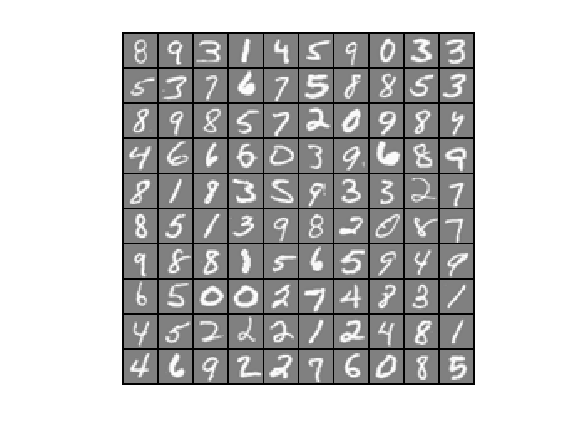

theta_t = [-2; -1; 1; 2];
X_t = [ones(5,1) reshape(1:15,5,3)/10];
y_t = ([1;0;1;0;1] >= 0.5);
lambda_t = 3;
[J, grad] = lrCostFunction(theta_t, X_t, y_t, lambda_t);


fprintf('Cost: %f | Expected cost: 2.534819\n',J);
fprintf('Gradients:\n'); fprintf('%f\n',grad);
fprintf('Expected gradients:\n 0.146561\n -0.548558\n 0.724722\n 1.398003');

**MATLAB Tip:** When implementing the vectorization for regularized logistic regression, you might often want to only sum and update certain elements of $\theta$. In MATLAB, you can index into the matrices to access and update only certain elements. For example, `A(:,3:5)= B(:, 1:3)` will replace columns 3 to 5 of `A` with the columns 1 to 3 from `B`. One special keyword you can use in indexing is the `end` keyword in indexing. This allows us to select columns (or rows) until the end of the matrix. For example, `A(:, 2:end)` will only return elements from the 2nd to last column of `A`. Thus, you could use this together with the `sum` and `.^` operations to compute the sum of only the elements you are interested in (e.g. `sum(z(2:end).^2))`. In the starter code,` lrCostFunction.m`, we have also provided hints on yet another possible method computing the regularized gradient.

*You should now submit your solutions.  Enter *`submit`* at the command prompt, then enter or confirm your login and token when prompted.*

### 1.4 One-vs-all classication

In this part of the exercise, you will implement one-vs-all classification by training multiple regularized logistic regression classifiers, one for each of the $K$ classes in our dataset (Figure 1). In the handwritten digits dataset, $K = 10$, but your code should work for any value of $K$. 

    You should now complete the code in `oneVsAll.m` to train one classifier for each class. In particular, your code should return all the classifier parameters in a matrix $\Theta \in \mathbb{R}^{K\times(N+1)}$, where each row of $\Theta$ corresponds to the learned logistic regression parameters for one class. You can do this with a `for` loop from 1 to `K`, training each classifier independently.

Note that the `y` argument to this function is a vector of labels from 1 to 10, where we have mapped the digit '0' to the label 10 (to avoid confusions with indexing). When training the classifier for class $k \in \{1,\ldots,K\},$ you will want a $m$-dimensional vector of labels $y,$ where $y_j\in \{0,\;1\}$ indicates whether the $j$-th training instance belongs to class $k\; (y_j = 1)$, or if it belongs to a different class $(y_j = 0).$ You may find logical arrays helpful for this task.

**MATLAB Tip**: Logical arrays in MATLAB are arrays which contain binary (0 or 1) elements. In MATLAB, evaluating the expression `a == b` for a vector `a` (of size $m\times1$) and scalar `b` will return a vector of the same size as `a` with ones at positions where the elements of `a` are equal to `b` and zeroes where they are different. To see how this works for yourself, run the following code:

a = 1:10; % Create a and b
b = 3;
disp(a == b) % You should try different values of b here

Furthermore, you will be using `fmincg` for this exercise (instead of `fminunc`). `fmincg` works similarly to `fminunc`, but is more more efficient for dealing with a large number of parameters. After you have correctly completed the code for `oneVsAll.m`, run the code below to use your `oneVsAll` function to train a multi-class classifier.

num_labels = 10; % 10 labels, from 1 to 10 
lambda = 0.1;

J = 2.5348

[all_theta] = oneVsAll(X, y, num_labels, lambda);

*You should now submit your solutions.  Enter *`submit`* at the command prompt, then enter or confirm your login and token when prompted.*

#### 1.4.1 One-vs-all prediction

After training your one-vs-all classifier, you can now use it to predict the digit contained in a given image. For each input, you should compute the 'probability' that it belongs to each class using the trained logistic regression classifiers. Your one-vs-all prediction function will pick the class for which the corresponding logistic regression classifier outputs the highest probability and return the class label $(1, 2,..., \text{ or } K)$ as the prediction for the input example.

    You should now complete the code in `predictOneVsAll.m` to use the one-vs-all classifier to make predictions. Once you are done, run the code below to call your `predictOneVsAll` function using the learned value of $\Theta$. You should see that the training set  accuracy is about 94.9% (i.e., it classifies 94.9% of the examples in the training set correctly).

pred = predictOneVsAll(all_theta, X)

Cost: 2.534819 | Expected cost: 2.534819


Gradients:
0.146561
-0.548558
0.724722
1.398003


fprintf('\nTraining Set Accuracy: %f\n', mean(double(pred == y)) * 100);

Expected gradients:
 0.146561
 -0.548558
 0.724722
 1.398003

*You should now submit your solutions.  Enter *`submit`* at the command prompt, then enter or confirm your login and token when prompted.*

## 2. Neural Networks

In the previous part of this exercise, you implemented multi-class logistic regression to recognize handwritten digits. However, logistic regression cannot form more complex hypotheses as it is only a linear classier. (You could add more features such as polynomial features to logistic regression, but that can be very expensive to train*.) *In this part of the exercise, you will implement a neural network to recognize handwritten digits using the same training set as before. The neural network will be able to represent complex models that form non-linear hypotheses. 

    For this week, you will be using parameters from a neural network that we have already trained. Your goal is to implement the feedforward propagation algorithm to use our weights for prediction. In next week's exercise, you will write the backpropagation algorithm for learning the neural network parameters.

### 2.1 Model representation

Our neural network is shown in Figure 2. It has 3 layers- an input layer, a hidden layer and an output layer. Recall that our inputs are pixel values of digit images. Since the images are of size 20 x 20, this gives us 400 input layer units (excluding the extra bias unit which always outputs +1). As before, the training data will be loaded into the variables `X` and `y`.

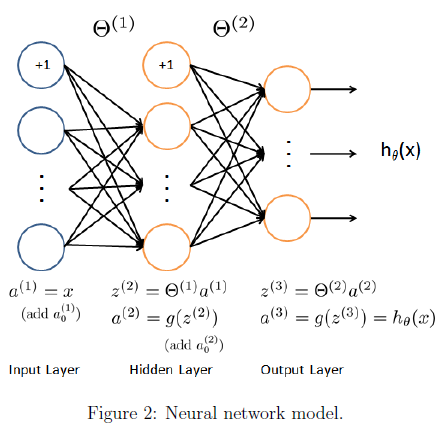

    You have been provided with a set of network parameters $(\Theta^{(1)},\Theta^{(2)})$ already trained by us. These are stored in `ex3weights.mat` and are loaded into `Theta1` and `Theta2 `by running the code below. The parameters have dimensions that are sized for a neural network with 25 units in the second layer and 10 output units (corresponding to the 10 digit classes).

load('ex3data1.mat');
m = size(X, 1);


   0   0   1   0   0   0   0   0   0   0



% Randomly select 100 data points to display
sel = randperm(size(X, 1));
sel = sel(1:100);
displayData(X(sel, :));


coded_class =      1     2     3     4     5     6     7     8     9    10


J = 0.6931

J = 0.2802

Iteration     1 | Cost: 2.802128e-01


J = 0.0945

Iteration     2 | Cost: 9.454389e-02


J = 1.2017

J = 0.0860

J = 0.0570

Iteration     3 | Cost: 5.704641e-02


J = 0.0839

J = 0.0469

Iteration     4 | Cost: 4.688190e-02


J = 0.0376

Iteration     5 | Cost: 3.759021e-02


J = 0.0835

J = 0.0352

Iteration     6 | Cost: 3.522008e-02


J = 0.0323

Iteration     7 | Cost: 3.234531e-02


J = 0.0364

J = 0.0315

Iteration     8 | Cost: 3.145034e-02


J = 0.0301

Iteration     9 | Cost: 3.008919e-02


J = 0.0345

J = 0.0299

Iteration    10 | Cost: 2.994639e-02


J = 0.0297

J = 0.0292

J = 0.0279

J = 0.0268

Iteration    11 | Cost: 2.678528e-02


J = 0.0828

J = 0.0267

J = 0.0266

Iteration    12 | Cost: 2.660323e-02


J = 0.0263

J = 0.0257

J = 0.0249

Iteration    13 | Cost: 2.493301e-02


J = 0.0362

J = 0.0248

Iteration    14 | Cost: 2.475211e-02


J = 0.0244

J = 0.0239

J = 0.0232

Iteration    15 | Cost: 2.318421e-02


J = 0.0280

J = 0.0229

Iteration    16 | Cost: 2.287050e-02


J = 0.0223

J = 0.0216

Iteration    17 | Cost: 2.160258e-02


J = 0.0220

J = 0.0212

Iteration    18 | Cost: 2.120371e-02


J = 0.0206

Iteration    19 | Cost: 2.064125e-02


J = 0.0221

J = 0.0206

Iteration    20 | Cost: 2.055695e-02


J = 0.0205

Iteration    21 | Cost: 2.045466e-02


J = 0.0203

J = 0.0203

Iteration    22 | Cost: 2.029177e-02


J = 0.0201

Iteration    23 | Cost: 2.005296e-02


J = 0.0200

J = 0.0200

Iteration    24 | Cost: 1.995949e-02


J = 0.0198

Iteration    25 | Cost: 1.982849e-02


J = 0.0198

Iteration    26 | Cost: 1.975129e-02


J = 0.0196

J = 0.0193

J = 0.0190

Iteration    27 | Cost: 1.897815e-02


J = 0.0225

J = 0.0189

Iteration    28 | Cost: 1.887065e-02


J = 0.0187

Iteration    29 | Cost: 1.869107e-02


J = 0.0187

J = 0.0186

Iteration    30 | Cost: 1.863223e-02


J = 0.0185

J = 0.0184

Iteration    31 | Cost: 1.837393e-02


J = 0.0182

Iteration    32 | Cost: 1.816950e-02


J = 0.0179

J = 0.0178

Iteration    33 | Cost: 1.781689e-02


J = 0.0191

J = 0.0177

Iteration    34 | Cost: 1.774664e-02


J = 0.0177

Iteration    35 | Cost: 1.767442e-02


J = 0.0176

Iteration    36 | Cost: 1.758469e-02


J = 0.0177

J = 0.0176

Iteration    37 | Cost: 1.756885e-02


J = 0.0175

J = 0.0175

Iteration    38 | Cost: 1.753424e-02


J = 0.0175

J = 0.0174

J = 0.0173

Iteration    39 | Cost: 1.728301e-02


J = 0.0170

Iteration    40 | Cost: 1.702078e-02


J = 0.0166

J = 0.0162

Iteration    41 | Cost: 1.621405e-02


J = 0.0155

Iteration    42 | Cost: 1.554757e-02


J = 0.0151

Iteration    43 | Cost: 1.506786e-02


J = 0.0150

J = 0.0147

Iteration    44 | Cost: 1.470387e-02


J = 0.0145

J = 0.0145

Iteration    45 | Cost: 1.445497e-02


J = 0.0143

Iteration    46 | Cost: 1.427905e-02


J = 0.0146

J = 0.0142

Iteration    47 | Cost: 1.420757e-02


J = 0.0141

J = 0.0139

Iteration    48 | Cost: 1.393436e-02


J = 0.0145

J = 0.0139

Iteration    49 | Cost: 1.388586e-02


J = 0.0138

Iteration    50 | Cost: 1.382167e-02


J = 0.6931

J = 0.3449

Iteration     1 | Cost: 3.448901e-01


J = 0.3151

Iteration     2 | Cost: 3.150694e-01


J = 0.1847

Iteration     3 | Cost: 1.846843e-01


J = NaN

J = NaN

J = NaN

J = 0.1849

J = 0.1699

Iteration     4 | Cost: 1.699017e-01


J = 0.1530

Iteration     5 | Cost: 1.529566e-01


J = 0.1317

Iteration     6 | Cost: 1.317377e-01


J = 0.1172

Iteration     7 | Cost: 1.171533e-01


J = 0.1137

J = 0.1074

Iteration     8 | Cost: 1.074286e-01


J = 0.0953

Iteration     9 | Cost: 9.531806e-02


J = 0.1086

J = 0.0930

Iteration    10 | Cost: 9.301912e-02


J = 0.0886

J = 0.0842

Iteration    11 | Cost: 8.418356e-02


J = 0.0981

J = 0.0819

Iteration    12 | Cost: 8.186322e-02


J = 0.0787

J = 0.0774

Iteration    13 | Cost: 7.743126e-02


J = 0.0878

J = 0.0765

Iteration    14 | Cost: 7.645181e-02


J = 0.0746

J = 0.0721

Iteration    15 | Cost: 7.209877e-02


J = 0.1484

J = 0.0721

J = 0.0720

Iteration    16 | Cost: 7.195896e-02


J = 0.0717

J = 0.0713

J = 0.0711

Iteration    17 | Cost: 7.106302e-02


J = 0.0729

J = 0.0708

Iteration    18 | Cost: 7.081516e-02


J = 0.0704

J = 0.0698

Iteration    19 | Cost: 6.984782e-02


J = 0.0691

Iteration    20 | Cost: 6.908892e-02


J = 0.0682

Iteration    21 | Cost: 6.818820e-02


J = 0.0703

J = 0.0680

Iteration    22 | Cost: 6.804182e-02


J = 0.0679

Iteration    23 | Cost: 6.788125e-02


J = 0.0678

J = 0.0678

Iteration    24 | Cost: 6.779397e-02


J = 0.0677

Iteration    25 | Cost: 6.767277e-02


J = 0.0676

Iteration    26 | Cost: 6.760372e-02


J = 0.0675

J = 0.0674

Iteration    27 | Cost: 6.740638e-02


J = 0.0674

J = 0.0673

Iteration    28 | Cost: 6.731728e-02


J = 0.0672

J = 0.0670

Iteration    29 | Cost: 6.698888e-02


J = 0.0676

J = 0.0669

Iteration    30 | Cost: 6.692984e-02


J = 0.0668

J = 0.0666

J = 0.0663

Iteration    31 | Cost: 6.630404e-02


J = 0.0665

J = 0.0661

Iteration    32 | Cost: 6.606809e-02


J = 0.0656

J = 0.0650

J = 0.0647

Iteration    33 | Cost: 6.466816e-02


J = 0.0665

J = 0.0643

Iteration    34 | Cost: 6.426962e-02


J = 0.0635

J = 0.0627

Iteration    35 | Cost: 6.267791e-02


J = 0.0709

J = 0.0625

Iteration    36 | Cost: 6.251576e-02


J = 0.0623

J = 0.0620

Iteration    37 | Cost: 6.202834e-02


J = 0.0625

J = 0.0619

Iteration    38 | Cost: 6.188522e-02


J = 0.0616

J = 0.0611

J = 0.0601

Iteration    39 | Cost: 6.013896e-02


J = 0.0594

Iteration    40 | Cost: 5.937078e-02


J = 0.0603

J = 0.0589

Iteration    41 | Cost: 5.888593e-02


J = 0.0589

J = 0.0586

Iteration    42 | Cost: 5.862828e-02


J = 0.0589

J = 0.0585

Iteration    43 | Cost: 5.854428e-02


J = 0.0585

Iteration    44 | Cost: 5.847598e-02


J = 0.0584

Iteration    45 | Cost: 5.840091e-02


J = 0.0583

J = 0.0581

Iteration    46 | Cost: 5.812346e-02


J = 0.0583

J = 0.0580

Iteration    47 | Cost: 5.803255e-02


J = 0.0579

J = 0.0577

Iteration    48 | Cost: 5.773511e-02


J = 0.0579

J = 0.0576

Iteration    49 | Cost: 5.763073e-02


J = 0.0574

J = 0.0573

Iteration    50 | Cost: 5.725251e-02


J = 0.6931

J = 0.3457

Iteration     1 | Cost: 3.456557e-01


J = 0.4052

J = 0.2179

Iteration     2 | Cost: 2.179164e-01


J = 0.1784

Iteration     3 | Cost: 1.784174e-01


J = NaN

J = 0.2436

J = 0.1679

Iteration     4 | Cost: 1.678808e-01


J = 0.1489

J = 0.1427

Iteration     5 | Cost: 1.427129e-01


J = 0.1150

Iteration     6 | Cost: 1.150393e-01


J = 0.1233

J = 0.1064

Iteration     7 | Cost: 1.063718e-01


J = 0.0971

Iteration     8 | Cost: 9.707803e-02


J = 0.1283

J = 0.0952

Iteration     9 | Cost: 9.518367e-02


J = 0.0924

J = 0.0904

Iteration    10 | Cost: 9.035733e-02


J = 0.1062

J = 0.0893

Iteration    11 | Cost: 8.928846e-02


J = 0.0875

J = 0.0853

Iteration    12 | Cost: 8.531186e-02


J = 0.0840

J = 0.0833

Iteration    13 | Cost: 8.333526e-02


J = 0.0805

Iteration    14 | Cost: 8.052683e-02


J = 0.0798

J = 0.0793

Iteration    15 | Cost: 7.932857e-02


J = 0.0775

J = 0.0767

Iteration    16 | Cost: 7.672637e-02


J = 0.0753

Iteration    17 | Cost: 7.530942e-02


J = 0.0882

J = 0.0750

Iteration    18 | Cost: 7.500108e-02


J = 0.0745

Iteration    19 | Cost: 7.445295e-02


J = 0.0739

Iteration    20 | Cost: 7.391453e-02


J = 0.0735

Iteration    21 | Cost: 7.349869e-02


J = 0.0731

Iteration    22 | Cost: 7.307295e-02


J = 0.0737

J = 0.0730

Iteration    23 | Cost: 7.296937e-02


J = 0.0728

J = 0.0726

Iteration    24 | Cost: 7.262398e-02


J = 0.0721

J = 0.0713

Iteration    25 | Cost: 7.129794e-02


J = 0.0763

J = 0.0712

Iteration    26 | Cost: 7.118480e-02


J = 0.0710

J = 0.0709

Iteration    27 | Cost: 7.089717e-02


J = 0.0704

J = 0.0696

Iteration    28 | Cost: 6.963444e-02


J = 0.0961

J = 0.0697

J = 0.0696

Iteration    29 | Cost: 6.959800e-02


J = 0.0695

J = 0.0694

J = 0.0692

Iteration    30 | Cost: 6.916223e-02


J = 0.0689

Iteration    31 | Cost: 6.893775e-02


J = 0.0734

J = 0.0689

J = 0.0689

Iteration    32 | Cost: 6.891911e-02


J = 0.0689

J = 0.0688

J = 0.0687

Iteration    33 | Cost: 6.872539e-02


J = 0.0685

Iteration    34 | Cost: 6.853615e-02


J = 0.0689

J = 0.0685

Iteration    35 | Cost: 6.849591e-02


J = 0.0684

J = 0.0683

J = 0.0679

J = 0.0675

Iteration    36 | Cost: 6.754918e-02


J = 0.0681

J = 0.0672

Iteration    37 | Cost: 6.715510e-02


J = 0.0665

J = 0.0658

Iteration    38 | Cost: 6.582568e-02


J = 0.0769

J = 0.0657

Iteration    39 | Cost: 6.573859e-02


J = 0.0656

Iteration    40 | Cost: 6.557058e-02


J = 0.0654

J = 0.0652

Iteration    41 | Cost: 6.517156e-02


J = 0.0647

Iteration    42 | Cost: 6.466814e-02


J = 0.0646

J = 0.0645

Iteration    43 | Cost: 6.446136e-02


J = 0.0645

J = 0.0644

Iteration    44 | Cost: 6.436053e-02


J = 0.0644

J = 0.0643

Iteration    45 | Cost: 6.432190e-02


J = 0.0643

Iteration    46 | Cost: 6.428303e-02


J = 0.0643

J = 0.0643

Iteration    47 | Cost: 6.427257e-02


J = 0.0643

J = 0.0642

Iteration    48 | Cost: 6.424751e-02


J = 0.0642

Iteration    49 | Cost: 6.421334e-02


J = 0.0642

J = 0.0642

Iteration    50 | Cost: 6.415530e-02


J = 0.6931

J = 0.3205

Iteration     1 | Cost: 3.205301e-01


J = 0.3041

Iteration     2 | Cost: 3.040759e-01


J = 0.1649

Iteration     3 | Cost: 1.649080e-01


J = NaN

J = NaN

J = 0.2050

J = 0.1439

Iteration     4 | Cost: 1.438784e-01


J = 0.0942

Iteration     5 | Cost: 9.416994e-02


J = 0.3726

J = 0.0904

Iteration     6 | Cost: 9.044270e-02


J = 0.0829

J = 0.0750

Iteration     7 | Cost: 7.499076e-02


J = 0.1144

J = 0.0720

Iteration     8 | Cost: 7.202465e-02


J = 0.0676

J = 0.0631

Iteration     9 | Cost: 6.313221e-02


J = 0.0913

J = 0.0617

Iteration    10 | Cost: 6.168143e-02


J = 0.0593

J = 0.0576

Iteration    11 | Cost: 5.762801e-02


J = 0.0627

J = 0.0564

Iteration    12 | Cost: 5.638036e-02


J = 0.0552

Iteration    13 | Cost: 5.517793e-02


J = 0.0541

Iteration    14 | Cost: 5.405985e-02


J = 0.0533

Iteration    15 | Cost: 5.332997e-02


J = 0.0518

Iteration    16 | Cost: 5.177817e-02


J = 0.0502

Iteration    17 | Cost: 5.019780e-02


J = 0.0611

J = 0.0501

Iteration    18 | Cost: 5.009061e-02


J = 0.0499

J = 0.0496

J = 0.0493

Iteration    19 | Cost: 4.933097e-02


J = 0.0499

J = 0.0491

Iteration    20 | Cost: 4.906466e-02


J = 0.0486

J = 0.0480

Iteration    21 | Cost: 4.795494e-02


J = 0.0557

J = 0.0479

Iteration    22 | Cost: 4.787525e-02


J = 0.0477

J = 0.0475

J = 0.0474

Iteration    23 | Cost: 4.736360e-02


J = 0.0471

J = 0.0470

Iteration    24 | Cost: 4.703861e-02


J = 0.0465

J = 0.0459

Iteration    25 | Cost: 4.594099e-02


J = 0.0518

J = 0.0458

Iteration    26 | Cost: 4.581046e-02


J = 0.0456

J = 0.0452

J = 0.0444

Iteration    27 | Cost: 4.439923e-02


J = 0.0478

J = 0.0442

Iteration    28 | Cost: 4.419366e-02


J = 0.0438

J = 0.0435

Iteration    29 | Cost: 4.354881e-02


J = 0.0427

Iteration    30 | Cost: 4.267101e-02


J = 0.0484

J = 0.0426

Iteration    31 | Cost: 4.260373e-02


J = 0.0425

J = 0.0424

Iteration    32 | Cost: 4.239268e-02


J = 0.0424

J = 0.0423

Iteration    33 | Cost: 4.229376e-02


J = 0.0422

Iteration    34 | Cost: 4.215965e-02


J = 0.0420

Iteration    35 | Cost: 4.201409e-02


J = 0.0421

J = 0.0420

Iteration    36 | Cost: 4.197691e-02


J = 0.0419

Iteration    37 | Cost: 4.192200e-02


J = 0.0419

J = 0.0418

Iteration    38 | Cost: 4.184111e-02


J = 0.0417

J = 0.0415

Iteration    39 | Cost: 4.148555e-02


J = 0.0411

Iteration    40 | Cost: 4.114130e-02


J = 0.0409

Iteration    41 | Cost: 4.086216e-02


J = 0.0405

Iteration    42 | Cost: 4.052611e-02


J = 0.0412

J = 0.0405

Iteration    43 | Cost: 4.047361e-02


J = 0.0404

J = 0.0403

Iteration    44 | Cost: 4.030387e-02


J = 0.0400

J = 0.0397

Iteration    45 | Cost: 3.970444e-02


J = 0.0404

J = 0.0396

Iteration    46 | Cost: 3.957912e-02


J = 0.0395

Iteration    47 | Cost: 3.947755e-02


J = 0.0412

J = 0.0395

J = 0.0395

Iteration    48 | Cost: 3.946946e-02


J = 0.0395

J = 0.0394

Iteration    49 | Cost: 3.944450e-02


J = 0.0394

J = 0.0394

Iteration    50 | Cost: 3.938203e-02


J = 0.6931

J = 0.3314

Iteration     1 | Cost: 3.314410e-01


J = 0.3995

J = 0.2217

Iteration     2 | Cost: 2.217377e-01


J = 0.3208

J = 0.1929

Iteration     3 | Cost: 1.929205e-01


J = 0.1569

Iteration     4 | Cost: 1.568866e-01


J = 0.1822

J = 0.1318

Iteration     5 | Cost: 1.318005e-01


J = 0.1182

J = 0.1148

Iteration     6 | Cost: 1.147878e-01


J = 0.1637

J = 0.1124

Iteration     7 | Cost: 1.124131e-01


J = 0.1084

Iteration     8 | Cost: 1.083564e-01


J = 0.1087

J = 0.1069

Iteration     9 | Cost: 1.069107e-01


J = 0.1046

J = 0.1023

Iteration    10 | Cost: 1.022962e-01


J = 0.1183

J = 0.1017

Iteration    11 | Cost: 1.017049e-01


J = 0.1004

J = 0.0988

Iteration    12 | Cost: 9.879326e-02


J = 0.0977

J = 0.0973

Iteration    13 | Cost: 9.731696e-02


J = 0.0948

J = 0.0922

Iteration    14 | Cost: 9.216899e-02


J = 0.0930

J = 0.0903

Iteration    15 | Cost: 9.032623e-02


J = 0.0871

J = 0.0841

Iteration    16 | Cost: 8.409627e-02


J = 0.0856

J = 0.0814

Iteration    17 | Cost: 8.140204e-02


J = 0.0786

Iteration    18 | Cost: 7.863906e-02


J = 0.0946

J = 0.0784

Iteration    19 | Cost: 7.835122e-02


J = 0.0778

J = 0.0771

Iteration    20 | Cost: 7.711350e-02


J = 0.0777

J = 0.0767

Iteration    21 | Cost: 7.671192e-02


J = 0.0760

J = 0.0754

Iteration    22 | Cost: 7.538515e-02


J = 0.0792

J = 0.0752

Iteration    23 | Cost: 7.517315e-02


J = 0.0748

J = 0.0741

J = 0.0735

Iteration    24 | Cost: 7.352966e-02


J = 0.0736

J = 0.0727

Iteration    25 | Cost: 7.269690e-02


J = 0.0717

Iteration    26 | Cost: 7.167827e-02


J = 0.0756

J = 0.0716

Iteration    27 | Cost: 7.156798e-02


J = 0.0714

J = 0.0711

Iteration    28 | Cost: 7.107344e-02


J = 0.0706

Iteration    29 | Cost: 7.057249e-02


J = 0.0748

J = 0.0705

Iteration    30 | Cost: 7.054742e-02


J = 0.0705

Iteration    31 | Cost: 7.051131e-02


J = 0.0704

J = 0.0703

J = 0.0703

Iteration    32 | Cost: 7.027145e-02


J = 0.0703

J = 0.0702

Iteration    33 | Cost: 7.015020e-02


J = 0.0699

J = 0.0696

Iteration    34 | Cost: 6.963282e-02


J = 0.0692

Iteration    35 | Cost: 6.921892e-02


J = 0.0687

Iteration    36 | Cost: 6.867102e-02


J = 0.0724

J = 0.0686

Iteration    37 | Cost: 6.864035e-02


J = 0.0686

J = 0.0685

J = 0.0684

Iteration    38 | Cost: 6.838629e-02


J = 0.0689

J = 0.0683

Iteration    39 | Cost: 6.832040e-02


J = 0.0682

J = 0.0680

Iteration    40 | Cost: 6.803653e-02


J = 0.0678

Iteration    41 | Cost: 6.775374e-02


J = 0.0674

J = 0.0673

Iteration    42 | Cost: 6.726372e-02


J = 0.0668

Iteration    43 | Cost: 6.682657e-02


J = 0.0659

J = 0.0647

Iteration    44 | Cost: 6.474593e-02


J = 0.0653

J = 0.0641

Iteration    45 | Cost: 6.414325e-02


J = 0.0634

Iteration    46 | Cost: 6.344911e-02


J = 0.0629

Iteration    47 | Cost: 6.291305e-02


J = 0.0624

Iteration    48 | Cost: 6.235097e-02


J = 0.0620

Iteration    49 | Cost: 6.196262e-02


J = 0.0635

J = 0.0618

Iteration    50 | Cost: 6.182512e-02


J = 0.6931

J = 0.3355

Iteration     1 | Cost: 3.354875e-01


J = 0.2189

Iteration     2 | Cost: 2.188639e-01


J = 0.0977

Iteration     3 | Cost: 9.772130e-02


J = NaN

J = NaN

J = NaN

J = 0.1116

J = 0.0846

Iteration     4 | Cost: 8.460314e-02


J = 0.0599

Iteration     5 | Cost: 5.991024e-02


J = 0.0960

J = 0.0532

Iteration     6 | Cost: 5.318810e-02


J = 0.0452

Iteration     7 | Cost: 4.521935e-02


J = 0.0412

Iteration     8 | Cost: 4.117442e-02


J = 0.0558

J = 0.0398

Iteration     9 | Cost: 3.978801e-02


J = 0.0387

Iteration    10 | Cost: 3.874084e-02


J = 0.0381

Iteration    11 | Cost: 3.814846e-02


J = 0.0764

J = 0.0384

J = 0.0381

Iteration    12 | Cost: 3.812015e-02


J = 0.0381

J = 0.0380

J = 0.0379

Iteration    13 | Cost: 3.791387e-02


J = 0.0376

J = 0.0372

Iteration    14 | Cost: 3.720946e-02


J = 0.0362

J = 0.0358

Iteration    15 | Cost: 3.578365e-02


J = 0.0350

J = 0.0347

Iteration    16 | Cost: 3.474696e-02


J = 0.0340

Iteration    17 | Cost: 3.395842e-02


J = 0.0340

J = 0.0335

Iteration    18 | Cost: 3.351052e-02


J = 0.0335

J = 0.0333

Iteration    19 | Cost: 3.326145e-02


J = 0.0333

J = 0.0331

Iteration    20 | Cost: 3.314033e-02


J = 0.0329

J = 0.0325

J = 0.0318

Iteration    21 | Cost: 3.180976e-02


J = 0.0324

J = 0.0314

Iteration    22 | Cost: 3.138624e-02


J = 0.0307

J = 0.0301

Iteration    23 | Cost: 3.012590e-02


J = 0.0293

Iteration    24 | Cost: 2.930241e-02


J = 0.0304

J = 0.0289

Iteration    25 | Cost: 2.893187e-02


J = 0.0283

J = 0.0280

Iteration    26 | Cost: 2.802475e-02


J = 0.0267

Iteration    27 | Cost: 2.666013e-02


J = 0.0321

J = 0.0265

Iteration    28 | Cost: 2.654574e-02


J = 0.0263

J = 0.0260

J = 0.0257

Iteration    29 | Cost: 2.573053e-02


J = 0.0259

J = 0.0254

Iteration    30 | Cost: 2.537200e-02


J = 0.0252

Iteration    31 | Cost: 2.517240e-02


J = 0.0281

J = 0.0251

Iteration    32 | Cost: 2.513433e-02


J = 0.0251

J = 0.0250

Iteration    33 | Cost: 2.503069e-02


J = 0.0249

Iteration    34 | Cost: 2.494552e-02


J = 0.0256

J = 0.0249

Iteration    35 | Cost: 2.493218e-02


J = 0.0249

J = 0.0249

J = 0.0248

Iteration    36 | Cost: 2.480208e-02


J = 0.0246

J = 0.0243

Iteration    37 | Cost: 2.433123e-02


J = 0.0239

Iteration    38 | Cost: 2.390543e-02


J = 0.0234

Iteration    39 | Cost: 2.342341e-02


J = 0.0328

J = 0.0235

J = 0.0234

Iteration    40 | Cost: 2.341157e-02


J = 0.0234

J = 0.0234

J = 0.0233

Iteration    41 | Cost: 2.329626e-02


J = 0.0231

J = 0.0228

Iteration    42 | Cost: 2.284163e-02


J = 0.0229

J = 0.0227

Iteration    43 | Cost: 2.269920e-02


J = 0.0227

J = 0.0226

Iteration    44 | Cost: 2.261561e-02


J = 0.0225

J = 0.0224

Iteration    45 | Cost: 2.241298e-02


J = 0.0229

J = 0.0224

Iteration    46 | Cost: 2.236815e-02


J = 0.0223

J = 0.0222

J = 0.0221

Iteration    47 | Cost: 2.207017e-02


J = 0.0247

J = 0.0220

Iteration    48 | Cost: 2.203881e-02


J = 0.0220

J = 0.0219

J = 0.0218

Iteration    49 | Cost: 2.177406e-02


J = 0.0214

J = 0.0212

Iteration    50 | Cost: 2.124261e-02


J = 0.6931

J = 0.3143

Iteration     1 | Cost: 3.142799e-01


J = 0.1939

Iteration     2 | Cost: 1.938915e-01


J = 0.2320

J = 0.0986

Iteration     3 | Cost: 9.858322e-02


J = NaN

J = 0.1353

J = 0.0867

Iteration     4 | Cost: 8.666461e-02


J = 0.0852

J = 0.0652

Iteration     5 | Cost: 6.518233e-02


J = 0.1422

J = 0.0616

Iteration     6 | Cost: 6.163782e-02


J = 0.0589

Iteration     7 | Cost: 5.886007e-02


J = 0.0608

J = 0.0577

Iteration     8 | Cost: 5.773973e-02


J = 0.0559

J = 0.0533

Iteration     9 | Cost: 5.334455e-02


J = 0.0504

Iteration    10 | Cost: 5.036396e-02


J = 0.0717

J = 0.0499

Iteration    11 | Cost: 4.994868e-02


J = 0.0496

Iteration    12 | Cost: 4.964157e-02


J = 0.0496

J = 0.0495

Iteration    13 | Cost: 4.945483e-02


J = 0.0492

Iteration    14 | Cost: 4.920530e-02


J = 0.0489

J = 0.0488

Iteration    15 | Cost: 4.880147e-02


J = 0.0481

J = 0.0477

Iteration    16 | Cost: 4.766125e-02


J = 0.0468

Iteration    17 | Cost: 4.683578e-02


J = 0.0457

Iteration    18 | Cost: 4.573370e-02


J = 0.0451

Iteration    19 | Cost: 4.507942e-02


J = 0.0683

J = 0.0451

J = 0.0450

Iteration    20 | Cost: 4.501869e-02


J = 0.0449

J = 0.0447

J = 0.0443

Iteration    21 | Cost: 4.433528e-02


J = 0.0434

J = 0.0427

Iteration    22 | Cost: 4.271154e-02


J = 0.0540

J = 0.0425

Iteration    23 | Cost: 4.251498e-02


J = 0.0422

J = 0.0419

Iteration    24 | Cost: 4.191880e-02


J = 0.0431

J = 0.0418

Iteration    25 | Cost: 4.178635e-02


J = 0.0416

J = 0.0415

Iteration    26 | Cost: 4.147292e-02


J = 0.0422

J = 0.0414

Iteration    27 | Cost: 4.139877e-02


J = 0.0413

J = 0.0412

Iteration    28 | Cost: 4.119548e-02


J = 0.0409

J = 0.0405

Iteration    29 | Cost: 4.051792e-02


J = 0.0421

J = 0.0404

Iteration    30 | Cost: 4.039230e-02


J = 0.0402

J = 0.0398

Iteration    31 | Cost: 3.980247e-02


J = 0.0397

J = 0.0396

Iteration    32 | Cost: 3.956674e-02


J = 0.0392

J = 0.0388

Iteration    33 | Cost: 3.884194e-02


J = 0.0380

Iteration    34 | Cost: 3.804697e-02


J = 0.0377

Iteration    35 | Cost: 3.768766e-02


J = 0.0412

J = 0.0376

Iteration    36 | Cost: 3.759027e-02


J = 0.0375

Iteration    37 | Cost: 3.745246e-02


J = 0.0373

J = 0.0372

Iteration    38 | Cost: 3.719427e-02


J = 0.0386

J = 0.0372

Iteration    39 | Cost: 3.716049e-02


J = 0.0371

J = 0.0370

Iteration    40 | Cost: 3.701040e-02


J = 0.0376

J = 0.0370

Iteration    41 | Cost: 3.699715e-02


J = 0.0370

J = 0.0369

Iteration    42 | Cost: 3.694363e-02


J = 0.0369

Iteration    43 | Cost: 3.689194e-02


J = 0.0368

J = 0.0367

J = 0.0366

Iteration    44 | Cost: 3.662658e-02


J = 0.0364

Iteration    45 | Cost: 3.642474e-02


J = 0.0360

Iteration    46 | Cost: 3.603049e-02


J = 0.0356

Iteration    47 | Cost: 3.563804e-02


J = 0.0354

Iteration    48 | Cost: 3.541916e-02


J = 0.0357

J = 0.0353

Iteration    49 | Cost: 3.533578e-02


J = 0.0353

J = 0.0353

Iteration    50 | Cost: 3.528248e-02


J = 0.6931

J = 0.3693

Iteration     1 | Cost: 3.693354e-01


J = 0.4872

J = 0.2565

Iteration     2 | Cost: 2.565067e-01


J = 0.2370

Iteration     3 | Cost: 2.370476e-01


J = NaN

J = NaN

J = 0.3340

J = 0.2342

Iteration     4 | Cost: 2.341589e-01


J = 0.2213

J = 0.2104

Iteration     5 | Cost: 2.103654e-01


J = 0.1782

Iteration     6 | Cost: 1.781526e-01


J = 0.1734

J = 0.1660

Iteration     7 | Cost: 1.659830e-01


J = 0.1524

Iteration     8 | Cost: 1.523508e-01


J = 0.2290

J = 0.1507

Iteration     9 | Cost: 1.506519e-01


J = 0.1479

J = 0.1437

J = 0.1401

Iteration    10 | Cost: 1.400809e-01


J = 0.2039

J = 0.1383

Iteration    11 | Cost: 1.383318e-01


J = 0.1352

J = 0.1302

J = 0.1229

Iteration    12 | Cost: 1.229135e-01


J = 0.1982

J = 0.1206

Iteration    13 | Cost: 1.205599e-01


J = 0.1169

J = 0.1124

Iteration    14 | Cost: 1.123879e-01


J = 0.1248

J = 0.1111

Iteration    15 | Cost: 1.110733e-01


J = 0.1086

J = 0.1073

Iteration    16 | Cost: 1.073286e-01


J = 0.1410

J = 0.1069

Iteration    17 | Cost: 1.068798e-01


J = 0.1063

J = 0.1059

Iteration    18 | Cost: 1.058981e-01


J = 0.1089

J = 0.1057

Iteration    19 | Cost: 1.056835e-01


J = 0.1053

J = 0.1046

J = 0.1030

J = 0.1020

Iteration    20 | Cost: 1.019768e-01


J = 0.1114

J = 0.1010

Iteration    21 | Cost: 1.010370e-01


J = 0.0996

J = 0.0983

Iteration    22 | Cost: 9.828022e-02


J = 0.1235

J = 0.0981

Iteration    23 | Cost: 9.812436e-02


J = 0.0979

Iteration    24 | Cost: 9.792314e-02


J = 0.0975

J = 0.0969

Iteration    25 | Cost: 9.689705e-02


J = 0.1224

J = 0.0970

J = 0.0969

Iteration    26 | Cost: 9.686948e-02


J = 0.0968

J = 0.0967

J = 0.0965

J = 0.0963

Iteration    27 | Cost: 9.630516e-02


J = 0.0961

J = 0.0960

Iteration    28 | Cost: 9.595524e-02


J = 0.0953

J = 0.0944

Iteration    29 | Cost: 9.439663e-02


J = 0.0943

J = 0.0939

Iteration    30 | Cost: 9.385265e-02


J = 0.0934

Iteration    31 | Cost: 9.343079e-02


J = 0.0927

Iteration    32 | Cost: 9.268395e-02


J = 0.0919

Iteration    33 | Cost: 9.194399e-02


J = 0.0912

Iteration    34 | Cost: 9.122540e-02


J = 0.0911

J = 0.0909

Iteration    35 | Cost: 9.091229e-02


J = 0.0909

J = 0.0908

Iteration    36 | Cost: 9.075902e-02


J = 0.0906

Iteration    37 | Cost: 9.055123e-02


J = 0.0903

J = 0.0899

Iteration    38 | Cost: 8.988150e-02


J = 0.0898

J = 0.0896

Iteration    39 | Cost: 8.962480e-02


J = 0.0896

J = 0.0895

Iteration    40 | Cost: 8.948730e-02


J = 0.0893

Iteration    41 | Cost: 8.933836e-02


J = 0.0892

Iteration    42 | Cost: 8.918654e-02


J = 0.0900

J = 0.0892

Iteration    43 | Cost: 8.916806e-02


J = 0.0891

J = 0.0891

J = 0.0889

J = 0.0887

Iteration    44 | Cost: 8.865092e-02


J = 0.0892

J = 0.0885

Iteration    45 | Cost: 8.849717e-02


J = 0.0882

J = 0.0877

J = 0.0871

Iteration    46 | Cost: 8.709044e-02


J = 0.1033

J = 0.0870

Iteration    47 | Cost: 8.698556e-02


J = 0.0867

J = 0.0865

Iteration    48 | Cost: 8.652771e-02


J = 0.0859

Iteration    49 | Cost: 8.590727e-02


J = 0.0899

J = 0.0859

Iteration    50 | Cost: 8.587364e-02


J = 0.6931

J = 0.3369

Iteration     1 | Cost: 3.369306e-01


J = 0.6809

J = 0.2513

Iteration     2 | Cost: 2.513191e-01


J = 0.2358

Iteration     3 | Cost: 2.358271e-01


J = NaN

J = NaN

J = 0.5592

J = 0.2420

J = 0.2353

Iteration     4 | Cost: 2.352523e-01


J = 0.2337

J = 0.2306

J = 0.2219

J = 0.2011

J = 0.1867

Iteration     5 | Cost: 1.867055e-01


J = 0.1527

Iteration     6 | Cost: 1.526791e-01


J = 0.3630

J = 0.1504

J = 0.1488

Iteration     7 | Cost: 1.488460e-01


J = 0.1426

J = 0.1385

Iteration     8 | Cost: 1.385401e-01


J = 0.1754

J = 0.1363

Iteration     9 | Cost: 1.363013e-01


J = 0.1326

J = 0.1276

Iteration    10 | Cost: 1.276495e-01


J = 0.1349

J = 0.1259

Iteration    11 | Cost: 1.258539e-01


J = 0.1225

J = 0.1194

Iteration    12 | Cost: 1.193549e-01


J = 0.1140

Iteration    13 | Cost: 1.139919e-01


J = 0.1071

Iteration    14 | Cost: 1.070966e-01


J = 0.1053

J = 0.1037

Iteration    15 | Cost: 1.037065e-01


J = 0.0994

Iteration    16 | Cost: 9.936582e-02


J = 0.1157

J = 0.0988

Iteration    17 | Cost: 9.883916e-02


J = 0.0980

J = 0.0973

Iteration    18 | Cost: 9.734415e-02


J = 0.1023

J = 0.0971

Iteration    19 | Cost: 9.705827e-02


J = 0.0965

J = 0.0958

Iteration    20 | Cost: 9.578377e-02


J = 0.1030

J = 0.0957

Iteration    21 | Cost: 9.569713e-02


J = 0.0955

J = 0.0953

J = 0.0948

Iteration    22 | Cost: 9.483495e-02


J = 0.0947

J = 0.0944

Iteration    23 | Cost: 9.439928e-02


J = 0.0936

J = 0.0923

J = 0.0914

Iteration    24 | Cost: 9.143805e-02


J = 0.0990

J = 0.0908

Iteration    25 | Cost: 9.082974e-02


J = 0.0899

Iteration    26 | Cost: 8.992841e-02


J = 0.0922

J = 0.0898

Iteration    27 | Cost: 8.982376e-02


J = 0.0896

J = 0.0894

Iteration    28 | Cost: 8.939125e-02


J = 0.0892

Iteration    29 | Cost: 8.917813e-02


J = 0.0911

J = 0.0891

Iteration    30 | Cost: 8.913997e-02


J = 0.0891

J = 0.0889

J = 0.0888

Iteration    31 | Cost: 8.878267e-02


J = 0.0883

Iteration    32 | Cost: 8.832440e-02


J = 0.0884

J = 0.0882

Iteration    33 | Cost: 8.816147e-02


J = 0.0879

J = 0.0876

Iteration    34 | Cost: 8.757932e-02


J = 0.0879

J = 0.0874

Iteration    35 | Cost: 8.739009e-02


J = 0.0871

J = 0.0870

Iteration    36 | Cost: 8.699282e-02


J = 0.0890

J = 0.0869

Iteration    37 | Cost: 8.693568e-02


J = 0.0868

J = 0.0866

J = 0.0862

Iteration    38 | Cost: 8.623918e-02


J = 0.0888

J = 0.0862

Iteration    39 | Cost: 8.616863e-02


J = 0.0860

J = 0.0859

Iteration    40 | Cost: 8.587681e-02


J = 0.0857

Iteration    41 | Cost: 8.572493e-02


J = 0.0871

J = 0.0857

Iteration    42 | Cost: 8.569793e-02


J = 0.0856

J = 0.0856

J = 0.0854

Iteration    43 | Cost: 8.540541e-02


J = 0.0851

Iteration    44 | Cost: 8.508150e-02


J = 0.0854

J = 0.0850

Iteration    45 | Cost: 8.501001e-02


J = 0.0849

Iteration    46 | Cost: 8.492071e-02


J = 0.0848

J = 0.0846

J = 0.0844

Iteration    47 | Cost: 8.442055e-02


J = 0.0836

J = 0.0828

Iteration    48 | Cost: 8.278901e-02


J = 0.0814

Iteration    49 | Cost: 8.138520e-02


J = 0.0796

Iteration    50 | Cost: 7.962956e-02


J = 0.6931

J = 0.3478

Iteration     1 | Cost: 3.478011e-01


J = 0.2075

Iteration     2 | Cost: 2.074559e-01


J = 0.1108

Iteration     3 | Cost: 1.108108e-01


J = NaN

J = NaN

J = NaN

J = 0.1338

J = 0.0972

Iteration     4 | Cost: 9.723535e-02


J = 0.0671

J = 0.0485

Iteration     5 | Cost: 4.845901e-02


J = 2.9726

J = 0.0474

J = 0.0457

Iteration     6 | Cost: 4.571820e-02


J = 0.0408

J = 0.0341

Iteration     7 | Cost: 3.405605e-02


J = 0.1365

J = 0.0335

Iteration     8 | Cost: 3.350113e-02


J = 0.0320

J = 0.0299

J = 0.0283

Iteration     9 | Cost: 2.829574e-02


J = 0.0401

J = 0.0267

Iteration    10 | Cost: 2.671193e-02


J = 0.0244

J = 0.0229

Iteration    11 | Cost: 2.288809e-02


J = 0.1261

J = 0.0228

J = 0.0227

Iteration    12 | Cost: 2.267282e-02


J = 0.0223

J = 0.0216

J = 0.0205

Iteration    13 | Cost: 2.048262e-02


J = 0.0251

J = 0.0200

Iteration    14 | Cost: 2.001572e-02


J = 0.0192

J = 0.0182

Iteration    15 | Cost: 1.815609e-02


J = 0.0224

J = 0.0179

Iteration    16 | Cost: 1.791330e-02


J = 0.0175

J = 0.0172

Iteration    17 | Cost: 1.723808e-02


J = 0.0180

J = 0.0170

Iteration    18 | Cost: 1.702208e-02


J = 0.0166

J = 0.0163

Iteration    19 | Cost: 1.633115e-02


J = 0.0159

Iteration    20 | Cost: 1.586407e-02


J = 0.0162

J = 0.0156

Iteration    21 | Cost: 1.557474e-02


J = 0.0153

Iteration    22 | Cost: 1.528102e-02


J = 0.0150

Iteration    23 | Cost: 1.500042e-02


J = 0.0162

J = 0.0150

Iteration    24 | Cost: 1.495532e-02


J = 0.0149

J = 0.0147

J = 0.0146

Iteration    25 | Cost: 1.464703e-02


J = 0.0147

J = 0.0145

Iteration    26 | Cost: 1.450265e-02


J = 0.0143

J = 0.0140

Iteration    27 | Cost: 1.399742e-02


J = 0.0135

Iteration    28 | Cost: 1.345918e-02


J = 0.0132

Iteration    29 | Cost: 1.321219e-02


J = 0.0287

J = 0.0133

J = 0.0132

Iteration    30 | Cost: 1.320100e-02


J = 0.0132

J = 0.0131

J = 0.0130

J = 0.0129

Iteration    31 | Cost: 1.294498e-02


J = 0.0126

Iteration    32 | Cost: 1.260010e-02


J = 0.0141

J = 0.0126

Iteration    33 | Cost: 1.256812e-02


J = 0.0125

J = 0.0124

Iteration    34 | Cost: 1.243741e-02


J = 0.0124

Iteration    35 | Cost: 1.236271e-02


J = 0.0123

J = 0.0123

Iteration    36 | Cost: 1.230295e-02


J = 0.0122

Iteration    37 | Cost: 1.223889e-02


J = 0.0122

Iteration    38 | Cost: 1.217593e-02


J = 0.0122

J = 0.0121

Iteration    39 | Cost: 1.214861e-02


J = 0.0121

J = 0.0121

Iteration    40 | Cost: 1.208455e-02


J = 0.0120

J = 0.0118

J = 0.0115

Iteration    41 | Cost: 1.151305e-02


J = 0.0108

Iteration    42 | Cost: 1.075278e-02


J = 0.0102

Iteration    43 | Cost: 1.024856e-02


J = 0.0162

J = 0.0102

Iteration    44 | Cost: 1.020741e-02


J = 0.0105

J = 0.0102

Iteration    45 | Cost: 1.019881e-02


J = 0.0102

Iteration    46 | Cost: 1.018573e-02


J = 0.0102

J = 0.0102

Iteration    47 | Cost: 1.015313e-02


J = 0.0102

J = 0.0101

Iteration    48 | Cost: 1.014595e-02


J = 0.0101

J = 0.0101

J = 0.0101

Iteration    49 | Cost: 1.007013e-02


J = 0.0100

J = 0.0100

Iteration    50 | Cost: 1.003008e-02


% Load saved matrices from file
load('ex3weights.mat'); 
% Theta1 has size 25 x 401
% Theta2 has size 10 x 26

### 2.2 Feedforward propagation and prediction

Now you will implement feedforward propagation for the neural network. You will need to complete the code in `predict.m` to return the neural network's prediction. You should implement the feedforward computation that computes $h_\theta(x^{(i)})$ for every example $i$ and returns the associated predictions. Similar to the one-vs-all classication strategy, the prediction from the neural network will be the label that has the largest output $(h_\theta(x))_k$.

**Implementation Note: **The matrix `X` contains the examples in rows. When you complete the code in `predict.m`, you will need to add the column of 1's to the matrix. The matrices `Theta1` and `Theta2` contain the parameters for each unit in rows. Specically, the first row of `Theta1` corresponds to the first hidden unit in the second layer. In MATLAB, when you compute $z^{(2)} = \Theta^{(1)}a^{(1)}$, be sure that you index (and if necessary, transpose) `X` correctly so that you get $a^{(1)}$ as a column vector.

Once you are done, run the code below to call your predict function using the loaded set of parameters for `Theta1` and `Theta2`. You should see that the accuracy is about 97.5%.

pred = predict(Theta1, Theta2, X);

pred =     10
    10
    10
    10
    10
    10
    10
    10
    10
    10


fprintf('\nTraining Set Accuracy: %f\n', mean(double(pred == y)) * 100);

The code below will displaying images from the training set one at a time, while the console prints out the predicted label for the displayed image. Rerun to repeat with another image.

%  Randomly permute examples
rp = randi(m);


Training Set Accuracy: 94.880000


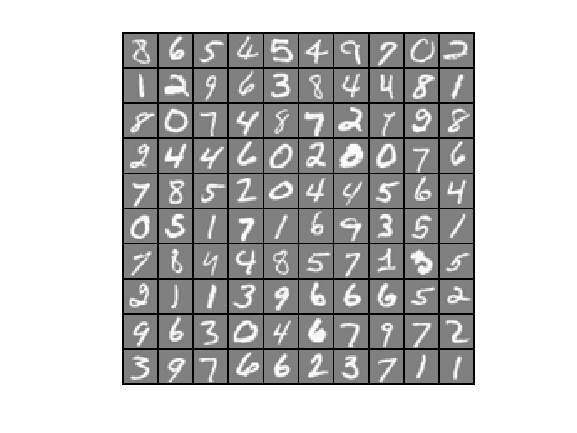

ans =           26        5000


ans =         5000          10



Training Set Accuracy: 97.520000



Neural Network Prediction: 9 (digit 9)


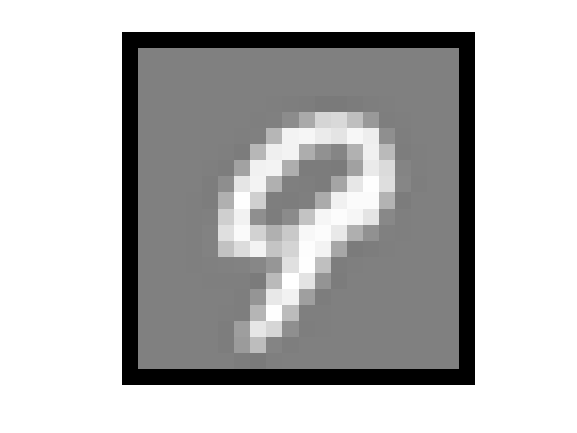

% Predict
pred = predict(Theta1, Theta2, X(rp,:));
fprintf('\nNeural Network Prediction: %d (digit %d)\n', pred, mod(pred, 10));
% Display 
displayData(X(rp, :));   

*You should now submit your solutions.  Enter *`submit`* at the command prompt, then enter or confirm your login and token when prompted.*

## Submission and Grading

After completing this assignment, be sure to use the submit function to submit your solutions to our servers. The following is a breakdown of how each part of this exercise is scored.

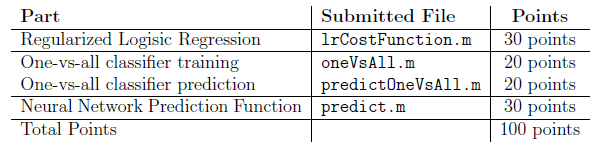

You are allowed to submit your solutions multiple times, and we will take only the highest score into consideration.